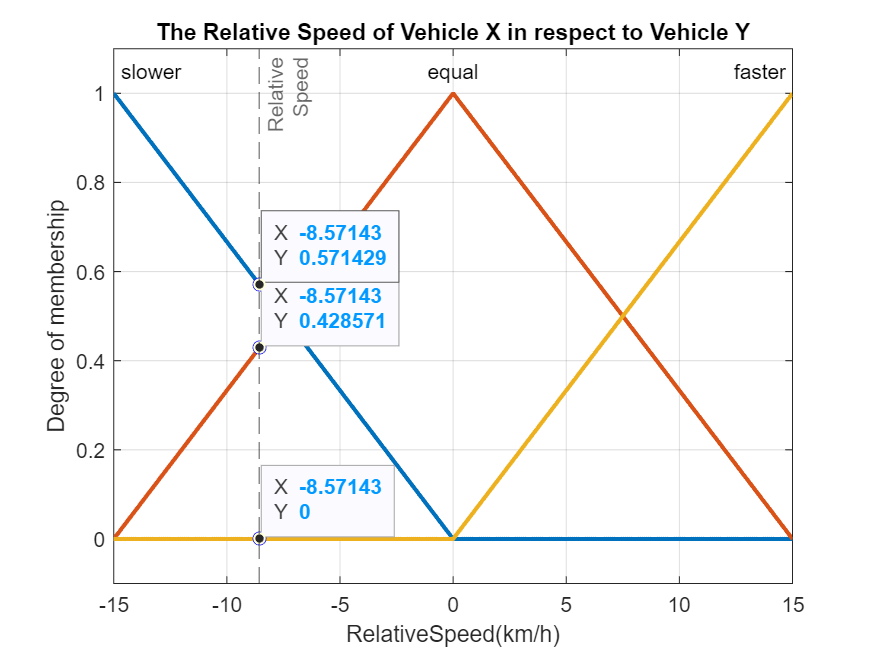

% Create FIS (Fuzzy Inferance System)
% With 2 input (with 3 membership functions) and 1 output (with 5 membership functions)

fuzzyFIS = mamfis(...
    'Name','Uses Binary MFs',...
    'NumInputs',2,'NumInputMFs',3,... % 2 Inputs and 3 Variables required for each input
    'NumOutputs',1,'NumOutputMFs',5,... % 1 Output and 5 variables required 
    'AddRule','none'... % For now include no rules
    );

% Creating Inputs (Relative Speed)
fuzzyFIS.Inputs(1).Name = 'RelativeSpeed'; % distance difference between the vehicles
fuzzyFIS.Inputs(1).Range = [-15 15]; % Overall range of the graph
fuzzyFIS.Inputs(1).MembershipFunctions(1).Name = "slower"; % The linguistic description
fuzzyFIS.Inputs(1).MembershipFunctions(1).Type = "linzmf"; % The type of graph
fuzzyFIS.Inputs(1).MembershipFunctions(1).Parameters = [-15 0]; % Declares the range
fuzzyFIS.Inputs(1).MembershipFunctions(2).Name = "equal"; % The linguistic description
fuzzyFIS.Inputs(1).MembershipFunctions(2).Type = "trimf"; % The type of graph
fuzzyFIS.Inputs(1).MembershipFunctions(2).Parameters = [-15 0 15]; % Declares the range
fuzzyFIS.Inputs(1).MembershipFunctions(3).Name = "faster"; % The linguistic description
fuzzyFIS.Inputs(1).MembershipFunctions(3).Type = "linsmf"; % The type of graph
fuzzyFIS.Inputs(1).MembershipFunctions(3).Parameters = [0 15]; % Declares the range
% Plotting Input MFs
plotmf(fuzzyFIS,'input',1,1000) % the more values, the more accurate 1000+ required
set(findall(gca, 'Type', 'Line'), 'lineWidth',2) % generates graphs based and forms in lines
grid on

hold on
% Updating Graph properties (Identifying the intersection coordinates)
relativeSpeed =-8.57143; % Setting a straight line on the x axis (slider will allow me to change value of relative speed)
degrees1 = evalmf(fuzzyFIS.Inputs(1).MembershipFunctions, relativeSpeed); % for any instance of x, it will determine the intersection of 3 membership functions with x
plot(relativeSpeed,degrees1, 'b.-','MarkerSize',20); % symbolise the point with blue dot

% Plotting Points of intersection (Click the arrow on the top right of the graph when hovering mouse over it, to enlarge the size)
chart = gca().Children(1);
y = evalmf(fuzzyFIS.Inputs(1).MembershipFunctions(1), relativeSpeed);
datatip(chart,relativeSpeed,y);

% Plotting Points of intersection (Click the arrow on the top right of the graph when hovering mouse over it, to enlarge the size)
chart2 = gca().Children(2);
y = evalmf(fuzzyFIS.Inputs(1).MembershipFunctions(2), relativeSpeed);
datatip(chart2,relativeSpeed,y);

% Plotting Points of intersection (Click the arrow on the top right of the graph when hovering mouse over it, to enlarge the size)
chart3 = gca().Children(3);
y = evalmf(fuzzyFIS.Inputs(1).MembershipFunctions(3), relativeSpeed);
datatip(chart3,relativeSpeed,y);
xline(relativeSpeed,'--',{'Relative','Speed'});
hold off;

% Graph Properties
title("The Relative Speed of Vehicle X in respect to Vehicle Y");
xlabel("RelativeSpeed(km/h)");
ylabel("Degree of membership");

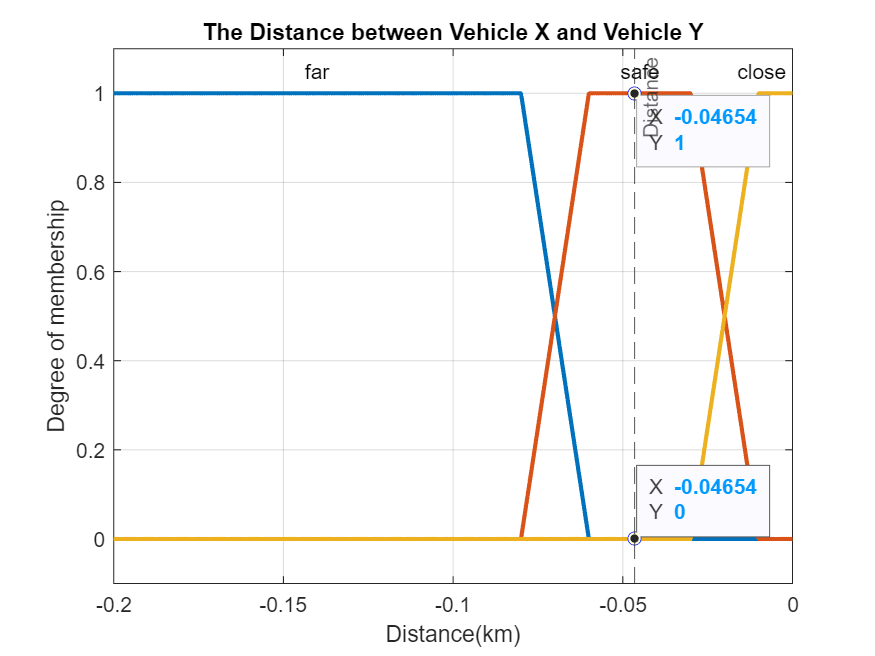



% Creating Inputs
fuzzyFIS.Inputs(2).Name = 'Distance'; % distance difference between the vechiles
fuzzyFIS.Inputs(2).Range = [-0.2 0]; % Modern Day laser sensors can detect to 200 metres in front of them
fuzzyFIS.Inputs(2).MembershipFunctions(1).Name = "far"; % The linguistic Description
fuzzyFIS.Inputs(2).MembershipFunctions(1).Type = "trapmf"; % The type of graph
fuzzyFIS.Inputs(2).MembershipFunctions(1).Parameters = [-0.2 -0.2 -0.08 -0.06]; % Declares the range
fuzzyFIS.Inputs(2).MembershipFunctions(2).Name = "safe"; % The linguistic Description
fuzzyFIS.Inputs(2).MembershipFunctions(2).Type = "trapmf"; % The type of graph
fuzzyFIS.Inputs(2).MembershipFunctions(2).Parameters = [-0.08 -0.06 -0.03 -0.01]; % Declares the range
fuzzyFIS.Inputs(2).MembershipFunctions(3).Name = "close"; % The linguistic Description
fuzzyFIS.Inputs(2).MembershipFunctions(3).Type = "trapmf"; % The type of graph
fuzzyFIS.Inputs(2).MembershipFunctions(3).Parameters = [-0.03 -0.01 0 0]; % Declares the range

plotmf(fuzzyFIS,'input',2,1000) % the more values, the more accurate !00+ required
set(findall(gca, 'Type', 'Line'), 'lineWidth', 2)
grid on

title("The Distance between Vehicle X and Vehicle Y");
xlabel("Distance(km)");
ylabel("Degree of membership");

hold on
% Updating Graph properties (Identifying the intersection coordinates)
relativeDistance =-0.04654; % Setting a straight line on the x axis (slider will allow me to change value of relative speed)

% Getting the intersection of all membership functions at line x = relativeDistance;
degrees2 = evalmf(fuzzyFIS.Inputs(2).MembershipFunctions, relativeDistance); % for any instance of x, it will determine the intersection of 3 membership functions with x
plot(relativeDistance,degrees2, 'b.-','MarkerSize',20); % symbolise the point with blue dot

% Plotting Points of intersection (Click the arrow on the top right of the graph when hovering mouse over it, to enlarge the size)
chart = gca().Children(1);
y = evalmf(fuzzyFIS.Inputs(2).MembershipFunctions(1), relativeDistance);
datatip(chart,relativeDistance,y);

% Plotting Points of intersection (Click the arrow on the top right of the graph when hovering mouse over it, to enlarge the size)
chart2 = gca().Children(2);
y = evalmf(fuzzyFIS.Inputs(2).MembershipFunctions(2), relativeDistance);
datatip(chart2,relativeDistance,y);

% Plotting Points of intersection (Click the arrow on the top right of the graph when hovering mouse over it, to enlarge the size)
chart3 = gca().Children(3);
y = evalmf(fuzzyFIS.Inputs(2).MembershipFunctions(3), relativeDistance);
datatip(chart3,relativeDistance,y);

xline(relativeDistance,'--',{'Distance'});
hold off;

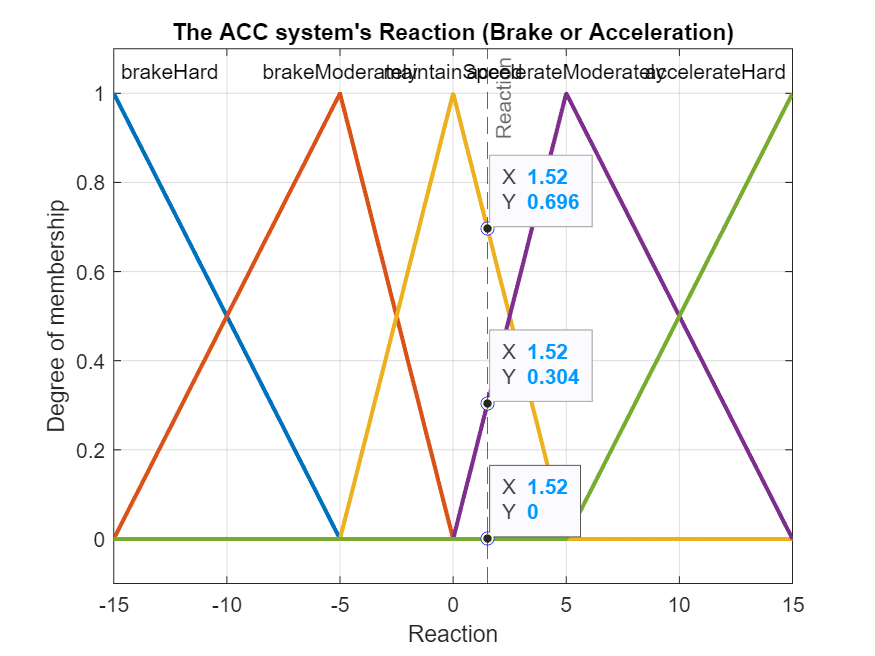



% Updating Graph properties

% the Output
fuzzyFIS.Outputs(1).Name = 'Reaction';
fuzzyFIS.Outputs(1).Range = [-15 15];
fuzzyFIS.Outputs(1).MembershipFunctions(1).Name = 'brakeHard';
fuzzyFIS.Outputs(1).MembershipFunctions(1).Type = 'linzmf';
fuzzyFIS.Outputs(1).MembershipFunctions(1).Parameters = [-15 -5];
fuzzyFIS.Outputs(1).MembershipFunctions(2).Name = 'brakeModerately';
fuzzyFIS.Outputs(1).MembershipFunctions(2).Type = 'trimf';
fuzzyFIS.Outputs(1).MembershipFunctions(2).Parameters = [-15 -5 0];
fuzzyFIS.Outputs(1).MembershipFunctions(3).Name = 'maintainSpeed';
fuzzyFIS.Outputs(1).MembershipFunctions(3).Type = 'trimf';
fuzzyFIS.Outputs(1).MembershipFunctions(3).Parameters = [-5 0 5];
fuzzyFIS.Outputs(1).MembershipFunctions(4).Name = 'accelerateModerately';
fuzzyFIS.Outputs(1).MembershipFunctions(4).Type = 'trimf';
fuzzyFIS.Outputs(1).MembershipFunctions(4).Parameters = [0 5 15];
fuzzyFIS.Outputs(1).MembershipFunctions(5).Name = 'accelerateHard';
fuzzyFIS.Outputs(1).MembershipFunctions(5).Type = 'linsmf';
fuzzyFIS.Outputs(1).MembershipFunctions(5).Parameters = [5 15];

% Plotting these MFs
plotmf(fuzzyFIS,'output',1,1500);
set(findall(gca, 'Type', 'Line'), 'lineWidth', 2);
grid on

% Updating Graph properties
legend("show")
legend({'brake hard','brake moderately','maintain speed', 'accelerate moderately', 'accelerate hard'},'FontSize',12)
legend("Position",[0.64202,0.23079,0.37321,0.25238])
legend off

title("The ACC system's Reaction (Brake or Acceleration)")
xlabel("Reaction")
ylabel("Degree of membership")

hold on
% Updating Graph properties (Identifying the intersection coordinates)
reaction =1.52; % Setting a straight line on the x axis (slider will allow me to change value of relative speed)

degrees3 = evalmf(fuzzyFIS.Outputs(1).MembershipFunctions, reaction); % for any instance of x, it will determine the intersection of 3 membership functions with x
plot(reaction,degrees3,'b.-','MarkerSize',20); % symbolise the point with blue dot

% Plotting Points of intersection (Click the arrow on the top right of the graph when hovering mouse over it, to enlarge the size)
chart = gca().Children(1);
y = evalmf(fuzzyFIS.Outputs(1).MembershipFunctions(1), reaction);
datatip(chart,reaction,y);

% Plotting Points of intersection (Click the arrow on the top right of the graph when hovering mouse over it, to enlarge the size)
chart2 = gca().Children(2);
y = evalmf(fuzzyFIS.Outputs(1).MembershipFunctions(2), reaction);
datatip(chart2,reaction,y);

% Plotting Points of intersection (Click the arrow on the top right of the graph when hovering mouse over it, to enlarge the size)
chart3 = gca().Children(3);
y = evalmf(fuzzyFIS.Outputs(1).MembershipFunctions(3), reaction);
datatip(chart3,reaction,y);

% Plotting Points of intersection (Click the arrow on the top right of the graph when hovering mouse over it, to enlarge the size)
chart4 = gca().Children(4);
y = evalmf(fuzzyFIS.Outputs(1).MembershipFunctions(4), reaction);
datatip(chart4,reaction,y);

% Plotting Points of intersection (Click the arrow on the top right of the graph when hovering mouse over it, to enlarge the size)
chart5 = gca().Children(5);
y = evalmf(fuzzyFIS.Outputs(1).MembershipFunctions(5), reaction);
datatip(chart5,reaction,y);

xline(reaction,'--',{'Reaction'});
hold off;

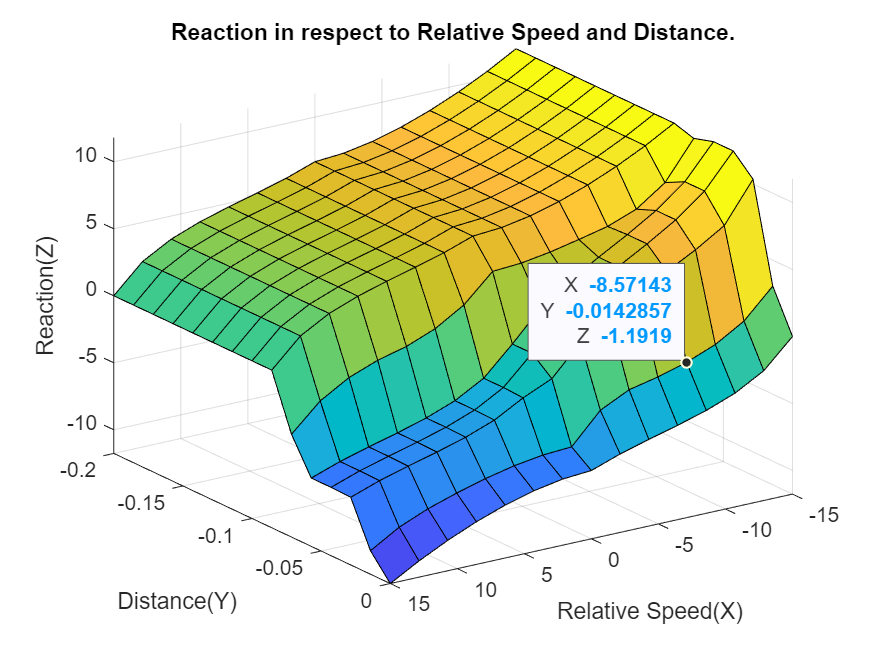


% Declaring the rules for the Fuzzy Inference System (Captisation is important in fuzzification)
% Is supported duing the inference system, and returns the fuzzy variables for crisp output
rules = ["if Distance is close and RelativeSpeed is slower then Reaction is maintainSpeed"...
         "if Distance is close and RelativeSpeed is equal then Reaction is brakeModerately"...
         "if Distance is close and RelativeSpeed is faster then Reaction is brakeHard"...
         "if Distance is safe and RelativeSpeed is slower then Reaction is accelerateHard"...
         "if Distance is safe and RelativeSpeed is equal then Reaction is maintainSpeed"...
         "if Distance is safe and RelativeSpeed is faster then Reaction is brakeModerately"...
         "if Distance is far and RelativeSpeed is slower then Reaction is accelerateHard"...
         "if Distance is far and RelativeSpeed is equal then Reaction is accelerateModerately"...
         "if Distance is far and RelativeSpeed is faster then Reaction is maintainSpeed"];

% Adding the Rules declared above into the Fuzzy system 
fuzzyFIS = addRule(fuzzyFIS,rules);

gensurf(fuzzyFIS);
view([-214.5 26.6]) % repositioing the graph so it is easier to view

title("Reaction in respect to Relative Speed and Distance.")
xlabel("Relative Speed(X)")
ylabel("Distance(Y)")
zlabel("Reaction(Z)")

ax = gca;
chart6 = ax.Children(1);
datatip(chart6,-8.571,-0.0142857,reaction); % provide a random point of the graph to prove that it contains logical values